# 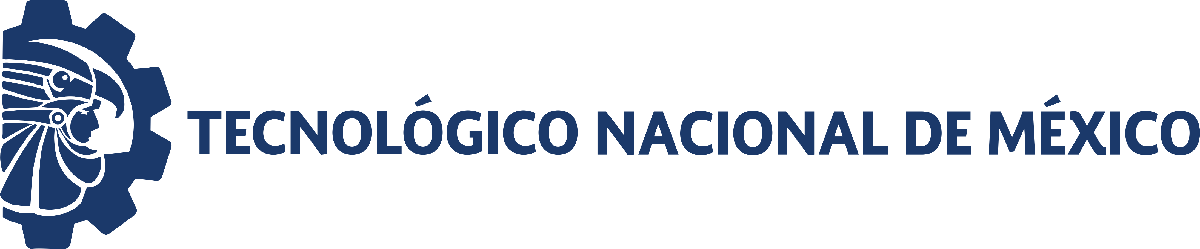

# **Modelizado de la levadura *****Saccharomyces cerevisiae***** para la producción de ethanol**

Paul A. Valle

Posgrado en Ciencias de la Ingeniería, Grupo de investigación [BioMath](https://biomath.xyz/), Tecnológico Nacional de México/IT Tijuana, Blvd. Alberto Limón Padilla s/n, Tijuana, C.P. 22454, B.C., México. Email: paul.valle@tectijuana.edu.mx

## Áreas del conocimiento

Ingeniería Biomédica; Ingeniería de Control; Ingeniería Bioquímica; Sistemas Dinámicos.

## Resumen

Los sistemas dinámicos son una rama de las Matemáticas y de la Física que se encargan de estudiar cómo evolucionan diversos tipos de sistemas a lo largo del tiempo, estos pueden ser físicos, biológicos, económicos o sociales, entre otros. El análisis de sistemas dinámicos es importante en la comprensión de fenómenos complejos y en la resolución de problemas prácticos en distintas áreas del conocimiento. En esta actividad se aplican conceptos de sistemas dinámicos y modelizado matemático para describir el proceso de producción de etanol mediante la levadura *Saccharomyces cerevisiae (S. cerevisiae) *cuando se utiliza un sustrato combinado de fructosa y glucosa.

La levadura *S. cerevisiae* es un microorganismo unicelular de gran importancia en la investigación biológica y en numerosas aplicaciones biotecnológicas, es conocida comúnmente como levadura de panadería o levadura de cerveza y es valorada por su versatilidad y su capacidad para fermentar una amplia gama de sustratos, produciendo etanol y dióxido de carbono como los principales metabolitos del proceso de fermentación.

El origen de los datos experimentales que se utilizan en el desarrollo de esta actividad es descrito por Páez-Lerma *et al*. en [https://doi.org/10.1080/08905436.2013.840788.](https://doi.org/10.1080/08905436.2013.840788.)

## Prerrequisitos

Las competencias previas que el alumno debe tener para desarrollar esta actividad de enseñanza son las siguientes:

- Emplea un lenguaje de programación para la solución de problemas.

- Emplea técnicas de modelado de sistemas para aplicaciones en procesos biológicos y fisiológicos.

- Aplica métodos numéricos para la solución de ecuaciones diferenciales ordinarias que permitan resolver problemas que involucran sistemas dinámicos en ingeniería.

- Entiende los conceptos de la teoría de la probabilidad y estadística para organizar, clasificar, analizar e interpretar datos para la toma decisiones en aplicaciones de Ingeniería.

## Objetivos de aprendizaje

### Objetivo general

Integrar conceptos relacionados con sistemas dinámicos, sistemas biológicos, modelizado matemático-computacional de sistemas no lineales, análisis de datos, ajuste de ecuaciones diferenciales ordinarias de primer orden a datos experimentales mediante regresión no lineal y bioestadística.

### Objetivos específicos

- Conocer los antecedentes sobre la experimentación *in silico* y la implementación de modelos matemáticos con base en datos experimentales.

- Desarrollar modelos para la evolución de diversos sistemas biológicos y fisiológicos con base en las distintas leyes de crecimiento.

- Realizar análisis estadísticos, filtrados de datos experimentales y determina intervalos de confianza.

- Formular y ajustar modelos matemáticos de ecuaciones diferenciales ordinarias para definir estrategias de control con ayuda de la experimentación *in silico*.

## Antes de empezar

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Datos experimentales

**Actividad 1.** Cargar los datos experimentales desde un archivo tipo **csv** utilizando el **Task **[**Import** **Data**](https://la.mathworks.com/help/matlab/ref/importdatatask.html)** e identificar** las variables del tiempo [$t$], azúcares [$x_i \left(t\right)$] y etanol [$y_i \left(t\right)$], donde $i=1,2,3$ para las tres muestras registradas en el sustrato y en el producto.

clc; clear; close all; format shortEng; warning('off','all');
fprintf('xi(t): Azúcares [g/L] \nyi(t): Etanol [g/L]');

xi(t): Azúcares [g/L] 
yi(t): Etanol [g/L]

% Import data from text file
sys = readtable("C:\Users\Uchiha_Paul\Dropbox\SWP55\ITT\Biomatematicas\InSIlico_Practicas\Levaduras\Saccharomyces_cerevisiae\MATLAB\Normalized\/data.csv");

% Clear temporary variables
clear opts

% Display results
sys

sys = 10×7 table
    t        x1          x2          x3          y1          y2         y3   
    __    ________    ________    ________    ________    ________    _______

     0      0.9965           1     0.90575    0.050955    0.067614    0.06892
     8       0.909     0.99715     0.88491       0.179    0.085252    0.18863
    16     0.48429     0.74377      0.4886     0.56149     0.26049    0.54499
    24     0.10858       0.304    0.063975     0.91409     0.69525    0.91752
    32    0.077731    0.045825    0.051766     0.95182     0.91115    0.97322
    40    0.061289    0.027023     0.04729     0.95803     0.96734    0.94676
    48    0.056568    0.022465    0.039476     0.93092       0.935    0.99624
    56    0.055429     0.02279    0.033371

to = table2array(sys(:,1)); %Arreglo con el tiempo de registro de los datos experimentales
xr = table2array([sys(:,2),sys(:,3),sys(:,4)]); %Arreglo con los datos experimentales del sustrato
yr = table2array([sys(:,5),sys(:,6),sys(:,7)]); %Arreglo con los datos experimentales del producto

### Promedio de las muestras

**Actividad 2.** Aplicar la función [**mean**](https://la.mathworks.com/help/matlab/ref/mean.html) para calcular el promedio de las tres muestras. Descripción de la función: mean(A,dim) devuelve la media de la dimensión dim. Por ejemplo, si A es una matriz, mean(A,2) devuelve un vector columna que contiene la media de cada fila.

xm = mean(xr,2);
ym = mean(yr,2);
datam = array2table([to,xm,ym],'VariableNames',{'t [h]','xo(t)','yo(t)'}); disp(datam)

    t [h]     xo(t)       yo(t)  
    _____    ________    ________

      0       0.96742    0.062497
      8       0.93035     0.15096
     16       0.57222     0.45566
     24       0.15885     0.84229
     32      0.058441      0.9454
     40        0.0452     0.95737
     48      0.039503     0.95405
     56      0.037197     0.93941
     64      0.035867     0.96423
     72      0.028325     0.98655



**Actividad 3.** Desarrollar una función que permita ilustrar la dinámica de los datos experimentales promediados mediante un marcador en una figura con 1 fila y 2 columnas, cada panel con sus respectivas etiquetas en un dominio de $t\in \left\lbrack 0,72\right\rbrack$ con rangos de $x\in \left\lbrack 0,1\right\rbrack$ y$y\in \left\lbrack 0,1\right\rbrack$. Adicionalmente, la función debe exportar la figura en formatos pdf, png, svg y eps. Nota: Las funciones deben escribirse al final del Live Script.

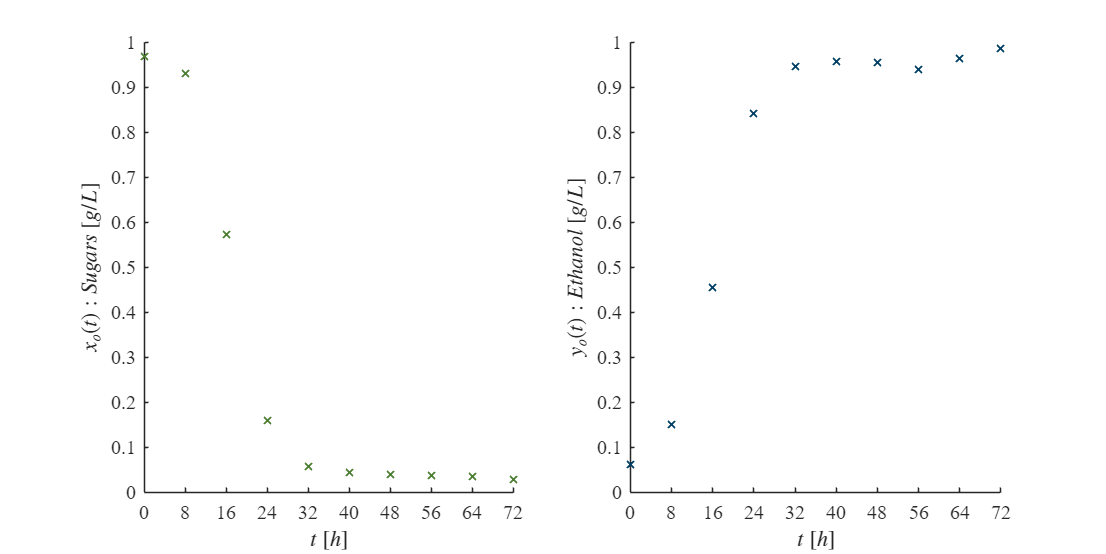

plotdata(to,xm,ym,1)

### Suavizado

[Suavizar señales](https://la.mathworks.com/help/signal/ug/signal-smoothing.html) permite descubrir patrones importantes en los datos mientras se omiten elementos que no son importantes (por ejemplo, ruido) mediante filtrado. El objetivo del suavizado es producir cambios lentos en el valor para que resulte más sencillo ver tendencias en los datos experimentales.

**Actividad 4.** Suavizar los datos experimentales promediados mediante la función [**smoothdata**](https://la.mathworks.com/help/matlab/ref/smoothdata.html?searchHighlight=smoothdata&s_tid=srchtitle_support_results_1_smoothdata) para comparar los distintos filtros disponibles. Nota: Utilice los controles **Drop Down** para la selección de los filtros y **Numeric Slider** para seleccionar el valor de la ventana en un intervalo de 1 a 10.

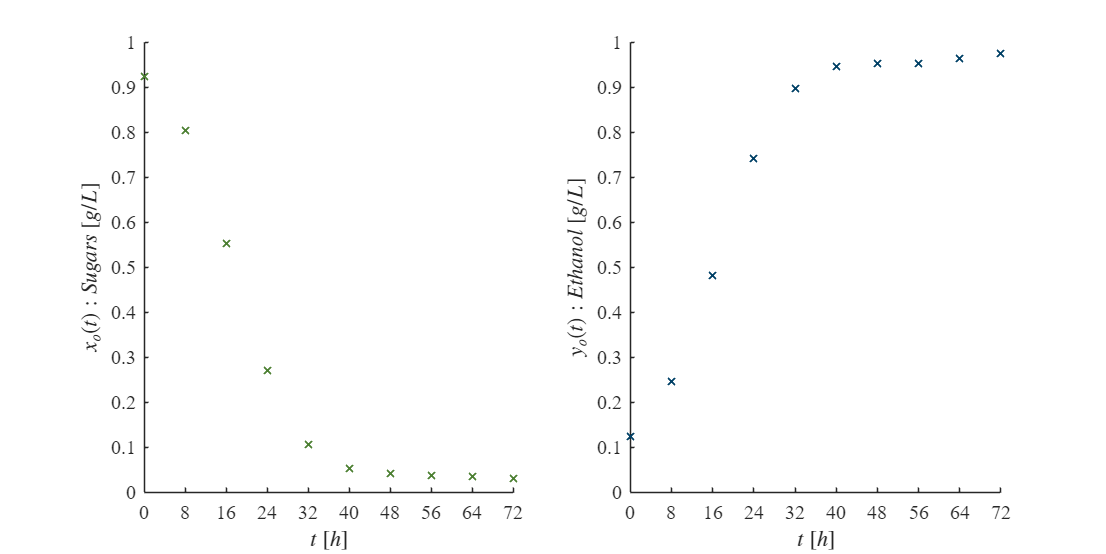

filtro = "gaussian";
ventana = 5;
xo = smoothdata(xm,filtro,ventana);
yo = smoothdata(ym,filtro,ventana);
plotdata(to,xo,yo,2)

## Regresión no lineal, bioestadísticos, bondad de ajuste y experimentación *in silico*

El modelo matemático propuesto para describir la dinámica de los datos experimentales de la fermentación se formula considerando la ley de acción de masas y la ley de decrecimiento exponencial, la primera para representar el consumo del sustrato y la producción del etanol debido a la interacción entre ambas variables, mientras que la segunda para representar la descomposición de los azúcares y la degradación del etanol. El sistema se compone de las siguientes dos ecuaciones diferenciales ordinarias no lineales de primer orden:


$$$\dot x = - \rho_3xy - \rho_1x,$
$\dot y = + \rho_4xy - \rho_2y,$$$


donde


$$\begin{array}{l}
\rho_1 :\mathrm{Tasa}\;\mathrm{de}\;\mathrm{descomposición}\;\mathrm{espontanea}\;\mathrm{no}-\mathrm{biológica}\;\mathrm{del}\;\mathrm{sustrato}\ldotp \\
\rho_2 :\mathrm{Tasa}\;\mathrm{de}\;\mathrm{degradación}\;\mathrm{del}\;\mathrm{etanol}\ldotp \\
\rho_3 :\mathrm{Tasa}\;\mathrm{de}\;\mathrm{consumo}\;\mathrm{del}\;\mathrm{sustrato}\;\mathrm{para}\;\mathrm{la}\;\mathrm{producción}\;\mathrm{del}\;\mathrm{etanol}\ldotp \\
\rho_4 :\mathrm{Tasa}\;\mathrm{de}\;\mathrm{conversión}\;\mathrm{del}\;\mathrm{sustrato}\;\mathrm{en}\;\mathrm{etanol}\;\mathrm{por}\;\mathrm{la}\;\mathrm{levadura}\ldotp 
\end{array}$$


**Actividad 5.** Calcular la tasa de descomposición del sustrato con base en su vida media asumiendo una [cinética de primer orden](https://www.khanacademy.org/science/ap-chemistry-beta/x2eef969c74e0d802:kinetics/x2eef969c74e0d802:concentration-changes-over-time/v/half-life-of-a-first-order-reaction): $\rho_1 =\frac{\ln \;2}{t_{1/2} }$, además es necesario establecer que $\rho_2$>$\rho_1$.

**Actividad 6.** Resolver el modelo de ecuaciones diferenciales con el método de Euler optimizado (método de Heun).

**Actividad 7.** Diseñar un algoritmo que permita ajustar el modelo matemático a los datos experimentales suavizados por regresión no lineal mediante la función [**fitnlm**](https://la.mathworks.com/help/stats/fitnlm.html?searchHighlight=fitnlm&s_tid=srchtitle_support_results_1_fitnlm).

**Actividad 8.** Presentar una tabla con los resultados correspondientes a la estimación de los parámetros $\rho_3$ y $\rho_4$, con su respectivo error estándar, margen de error, intervalos de confianza del 95 % y valor-P.

**Actividad 9.** Identificar las métricas de bondad de ajuste correspondientes al [coeficiente de determinación](https://la.mathworks.com/help/stats/coefficient-of-determination-r-squared.html?searchHighlight=R-squared&s_tid=srchtitle_support_results_1_R-squared) (R-cuadrada) y al [Criterio de Información de Akaike](https://la.mathworks.com/help/ident/ref/idmodel.aic.html) (ajustadas para [muestras pequeñas](https://la.mathworks.com/help/econ/aicbic.html): numObs/numParam < 40).

**Actividad 10.** Desarrollar una función que permita ilustrar los resultados del ajuste, es decir, se deben graficar los datos experimentales y los aproximados.

rho0 = [0.1;0.1];
[rho,SE,MoE,CI95,pValue,fa,mdl] = Variant(to,xo,yo,rho0);

Alpha: 0.05
Degrees of freedom: 18
t-Student value: 2.1009
rho1 = 0.00020671
rho2 = 0.00022738
    Parameters    Estimate       SE          MoE              CI95             pValue  
    __________    ________    _________    ________    __________________    __________

       rho3        0.1522     0.0043543    0.009148    0.14305    0.16135    5.3515e-18
       rho4       0.14436     0.0032414     0.00681    0.13755    0.15117    7.1689e-20



fxy = reshape(fa,[],2);
xa = fxy(:,1); ya = fxy(:,2);
fprintf(['\nR-squared:',num2str(mdl.Rsquared.Adjusted)]); fprintf(['\nAIC:',num2str(mdl.ModelCriterion.AICc)])


R-squared:0.99418
AIC:-78.6125

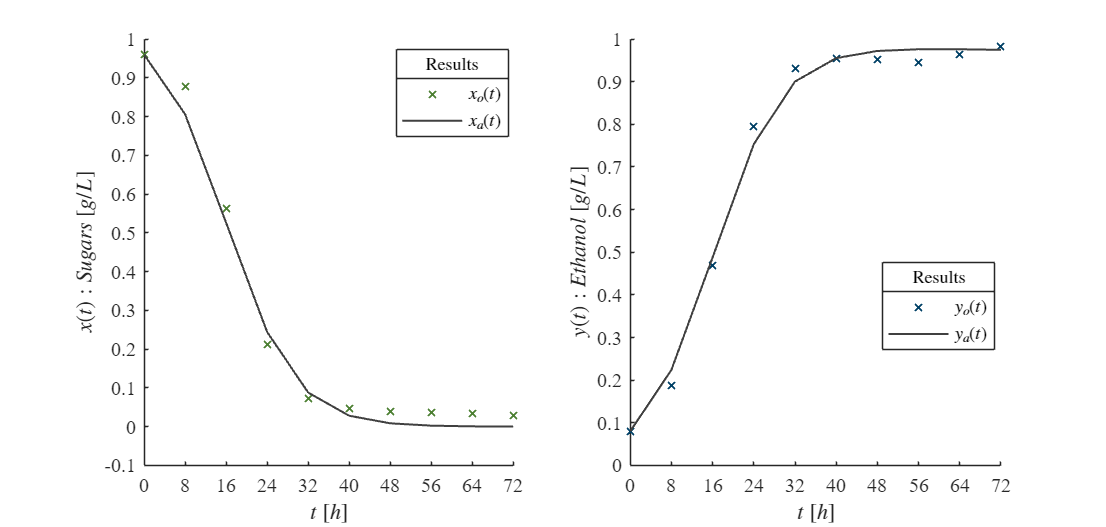

plotfit(to,[xo,xa],[yo,ya]);

## Funciones

### Datos experimentales

function plotdata(t,x,y,opt)
    set(figure(),'Color','w')
    FS = 10;
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    
    subplot(1,2,1)
    hold on
    plot(t,x,'x','LineWidth',1,'MarkerSize',5,'Color',[0.3,0.5,0.2])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$x_o(t):Sugars$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 1]); yticks(0:0.1:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,2,2)
    hold on
    plot(t,y,'x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$y_o(t):Ethanol$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 1]); yticks(0:0.1:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    if opt == 1
        exportgraphics(gcf,'datospromedio.pdf','ContentType','vector');
        exportgraphics(gcf,'datospromedio.png','ContentType','vector');
        print('datospromedio','-dsvg'); print('datospromedio','-depsc')
    elseif opt == 2
        exportgraphics(gcf,'datosuavizados.pdf','ContentType','vector');
        exportgraphics(gcf,'datosuavizados.png','ContentType','vector');
        print('datosuavizados','-dsvg'); print('datosuavizados','-depsc')
    end
end

### Modelo matemático, algoritmo de regresión no lineal y bioestadísticos

function [Estimate,SE,MoE,CI95,pValue,fa,mdl] = Variant(to,xo,yo,rho0)
    x0 = xo(1); y0 = yo(1);
    p1 = mean([log(2)/1680;log(2)/840960]);
    p2 = 1.1*p1;
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        p3 = p(1); p4 = p(2);
        dt = 1E-3;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;
    
        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);         
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end
        
        function [dx,dy] = f(x,y)
                dx = - p3*x*y - p1*x;
                dy = + p4*x*y - p2*y;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,rho0);
    
    fa = mdl.Fitted;
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pValue = table2array(mdl.Coefficients(:,4));
    CI95 = coefCI(mdl,0.05);
    dof = mdl.DFE;
    alpha = 0.05;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho3';'rho4'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pValue);
    fprintf(['Alpha: ',num2str(alpha),'\n'])
    fprintf(['Degrees of freedom: ',num2str(dof),'\n'])
    fprintf(['t-Student value: ',num2str(tval),'\n'])
    fprintf(['rho1 = ',num2str(p1),'\n'])
    fprintf(['rho2 = ',num2str(p2),'\n'])
    disp(Results)
end

### Resultados

function plotfit(t,x,y)
    set(figure(),'Color','w')
    FS = 10;
    set(gcf,'Units','Centimeters','Position',[2,2,21,10])
    
    subplot(1,2,1)
    hold on
    plot(t,x(:,1),'x','LineWidth',1,'MarkerSize',5,'Color',[0.3,0.5,0.2])
    plot(t,x(:,2),'-','LineWidth',1,'Color',[0.25,0.25,0.25])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t):Sugars$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([-0.1 1]); yticks(-0.1:0.1:1)
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','Best')
    title(L,'Results')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,2,2)
    hold on
    plot(t,y(:,1),'x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    plot(t,y(:,2),'-','LineWidth',1,'Color',[0.25,0.25,0.25])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t):Ethanol$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 1]); yticks(0:0.1:1)
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','Best')
    title(L,'Results')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'resultados.pdf','ContentType','vector');
    exportgraphics(gcf,'resultados.png','ContentType','vector');
    print('resultados','-dsvg'); print('resultados','-depsc')
end

## Referencias

Páez-Lerma, J. B., Arias-García, A., Rutiaga-Quiñones, O. M., Barrio, E., & Soto-Cruz, N. O. (2013). Yeasts isolated from the alcoholic fermentation of *Agave duranguensis* during mezcal production. *Food biotechnology*, *27*(4), 342-356. [https://doi.org/10.1080/08905436.2013.840788](https://doi.org/10.1080/08905436.2013.840788)

Walker, G. M., & Stewart, G. G. (2016). Saccharomyces cerevisiae in the production of fermented beverages. *Beverages*, *2*(4), 30. [https://doi.org/10.3390/beverages2040030](https://doi.org/10.3390/beverages2040030)

Salazar, Y., Valle, P. A., Rodríguez, E., Soto-Cruz, N. O., Páez-Lerma, J. B., & Reyes-Sánchez, F. J. (2023). Mechanistic modelling of biomass growth, glucose consumption and ethanol production by Kluyveromyces marxianus in batch fermentation. *Entropy*, *25*(3), 497. [https://doi.org/10.3390/e25030497](https://doi.org/10.3390/e25030497)

Wolfenden, R., & Yuan, Y. (2008). Rates of spontaneous cleavage of glucose, fructose, sucrose, and trehalose in water, and the catalytic proficiencies of invertase and trehalas. *Journal of the American Chemical Society*, *130*(24), 7548-7549. [https://doi.org/10.1021/ja802206s](https://doi.org/10.1021/ja802206s)

Motulsky, Harvey, and Arthur Christopoulos. Fitting models to biological data using linear and nonlinear regression: a practical guide to curve fitting. Oxford University Press, 2004.

Bryan, K. (2022). *Differential equations: A toolbox for modeling the world*. Simiode.

Garﬁnkel, A., Shevtsov, J., & Guo, Y. (2017). *Modeling life: the mathematics of biological systems*. Springer International Publishing AG.

## Semblanza

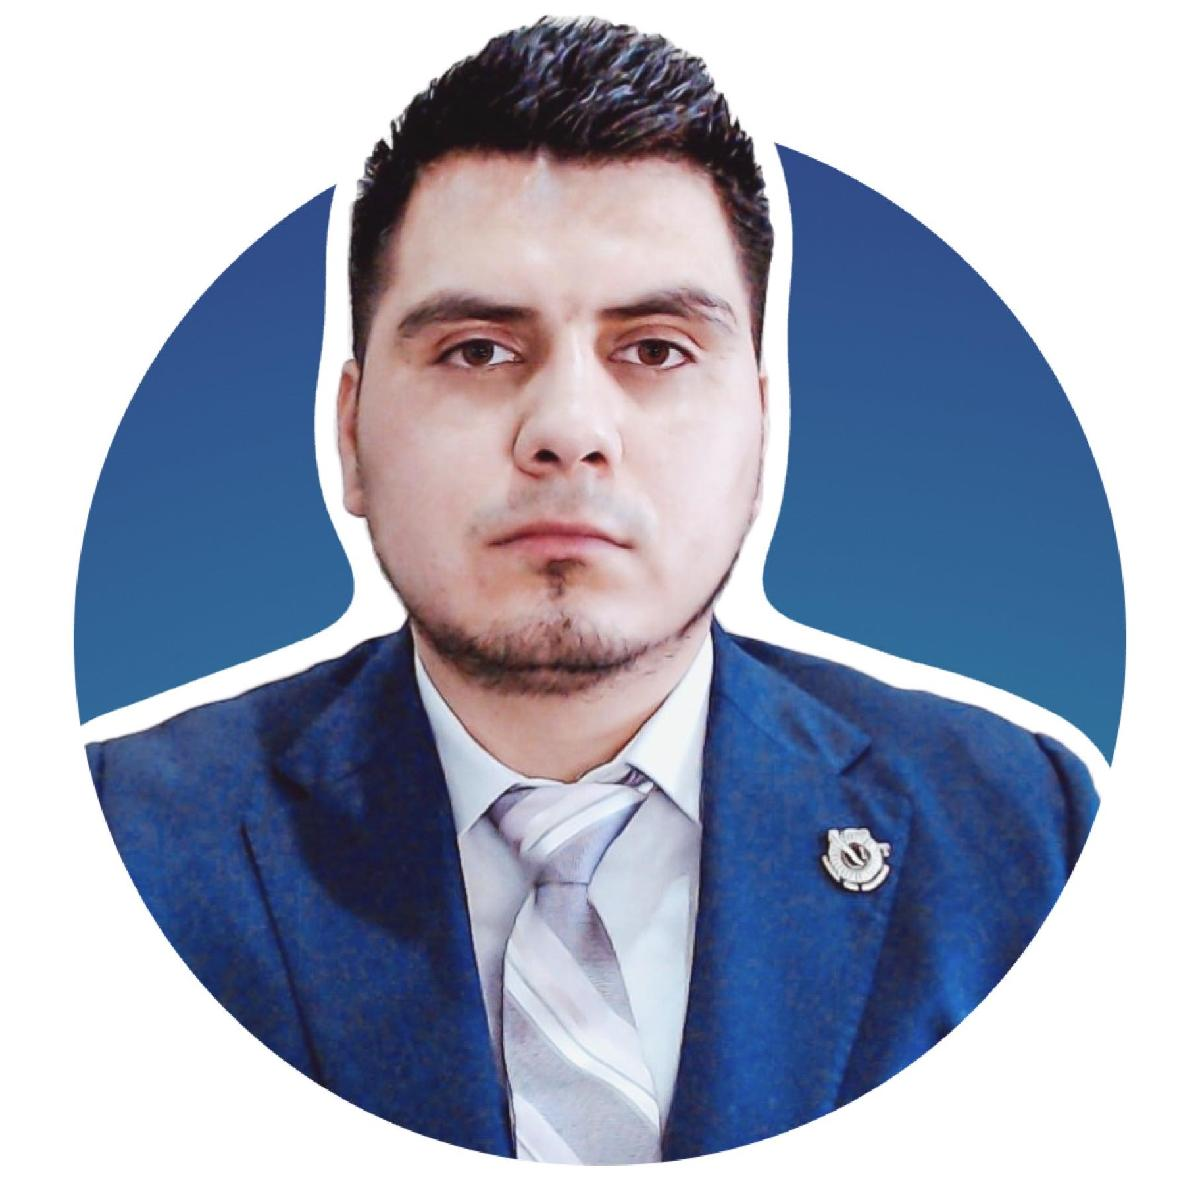

**Dr. Paul A. Valle**

*Investigador - Ingeniero - Profesor*

paul.valle@tectijuana.edu.mx

Paul Valle recibe el título de Ingeniero Electrónico con mención honorífica por el Instituto Tecnológico de Tijuana en el 2010. Obtiene los grados de Maestro en Ciencias en el 2012 y Doctor en Ciencias con mención honorífica en el 2016 por el Instituto Politécnico Nacional, ambos en el área de Biomatemáticas.

Actualmente es profesor titular en la carrera de [**Ingeniería Biomédica**](http://tectijuana.edu.mx/ing-biomedica/) del [**Instituto Tecnológico de Tijuana**](http://tectijuana.edu.mx/), Jefe de Proyectos de Investigación del Departamento de Ingeniería Eléctrica y Electrónica e Investigador en el Posgrado en Ciencias de la Ingeniería en los grados de [**maestría** ](https://www.tijuana.tecnm.mx/maestria-en-ciencias-de-la-ingenieria/)y [**doctorado**](https://www.tijuana.tecnm.mx/doctorado-en-ciencias-de-la-ingenieria/). Además, es integrante de la línea de investigación de Sistemas Dinámicos y Control, del Cuerpo Académico Sistemas Dinámicos No Lineales, de la Red Internacional de Control y Cómputo Aplicados y del [***Intercollegiate Biomathematics Alliance***](https://about.illinoisstate.edu/iba/). Pertenece al Sistema Nacional de Investigadores del CONAHCyT en nivel I y tiene reconocimiento a Perfil Deseable por la DGESU de la SEP. Finalmente, es fundador del grupo de investigación [**BioMath**](https://biomath.xyz/).